# ELEC-8103 – Modelling, Estimation, and Dynamic Systems

# Assignment 4

# Deadline: **5.11.2023 at 23:59**

# **Problem 1 (5 points)**

- **The goal of this task is to analyze the following dynamic system:**

## 
$$G\left(s\right)=\frac{1}{s^2 +3s+2}$$


## **a)**

- Create a transfer function model $G\left(s\right)$. **Hint: **Use [**tf**](https://se.mathworks.com/help/control/ref/tf.html).

- Generate a pseudorandom binary signal input with a sample rate of 10 Hz and with a duration of 200 seconds. **Hint**: Use [**idinput**](https://se.mathworks.com/help/ident/ref/idinput.html).

- Simulate the system’s response to the generated input signal. **Hint:** Use [**lsim**](https://se.mathworks.com/help/ident/ref/dynamicsystem.lsim.html).

- Create a figure and plot both the input and output signals of the model on two subplots.

**(1 point)**

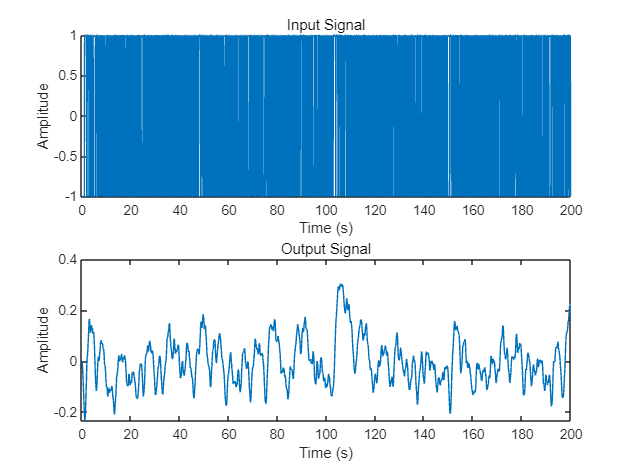

clear

warning off

%---------------------------------------------------------------
numerator = 1;
denominator = [1 3 2];
sample_rate = 10;
input_time = 200;
sys = tf(numerator, denominator);

sampleTime = 1/sample_rate;
t = 0:1/sample_rate:input_time;

u = idinput(length(t), 'prbs');

y = lsim(sys, u, t);

data = iddata(y,u,sampleTime);

figure;

subplot(2, 1, 1);
plot(t, u);
title('Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(t, y);
title('Output Signal');
xlabel('Time (s)');
ylabel('Amplitude');

%---------------------------------------------------------------

## **b)**

- Calculate the autocorrelation of the output signal computed in “a-3” above with a maximum lag of 200. **Hint**: Use [**xcorr**](https://se.mathworks.com/help/matlab/ref/xcorr.html).

- Create a figure and plot the autocorrelation signal. **Hint:** You can use [**stem**](https://se.mathworks.com/help/matlab/ref/stem.html?s_tid=doc_ta) for plotting.

** (1 point)**

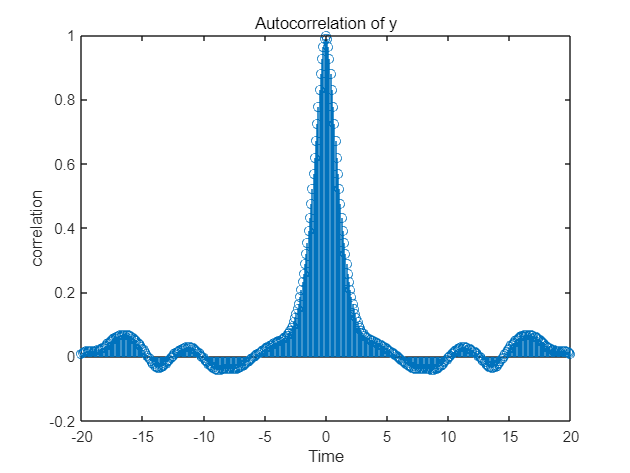

%---------------------------------------------------------------
[r,lags] = xcorr(y,200,'coeff');
figure;
stem(lags * sampleTime, r);
xlabel('Time');
ylabel('correlation');

title('Autocorrelation of y');

%---------------------------------------------------------------

## **c)**

- Estimate the impulse response of the system using correlation analysis for 10 seconds. Create a figure and plot the estimated impulse response. **Hint**: Use [**cra**](https://se.mathworks.com/help/ident/ref/cra.html?s_tid=doc_ta).

- On the same figure, plot the actual simulated impulse response of the system, using the transfer function directly, for 10 seconds. **Hint:** Use [**impulse**](https://se.mathworks.com/help/ident/ref/dynamicsystem.impulse.html?s_tid=doc_ta).

** (2 points) **

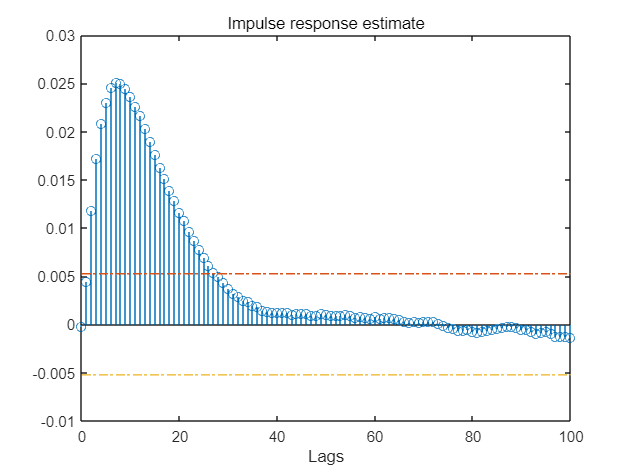

%---------------------------------------------------------------
% Estimate the impulse response using correlation analysis (cra)
ir = cra(u, y,100);

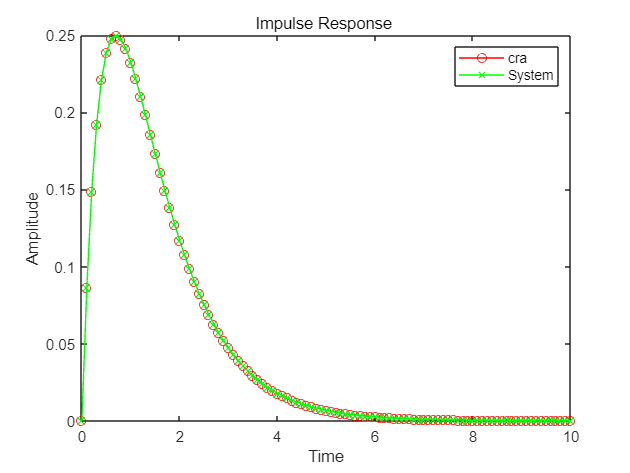

[ir, finaltime] = impulse(sys, 0:0.1:10);

figure;

plot(finaltime, ir, 'r', 'Marker', 'o'); 

hold on;  

plot(finaltime, ir, 'g', 'Marker', 'x');  


legend('cra', 'System');

title('Impulse Response ');
xlabel('Time');
ylabel('Amplitude');

%---------------------------------------------------------------

## **d)**

- Estimate the frequency response of the system using spectral analysis. **Hint: **Use [**spa**](https://se.mathworks.com/help/ident/ref/spa.html).

- Estimate the transfer function using the ETFE method. **Hint: **Use [**etfe**](https://se.mathworks.com/help/ident/ref/etfe.html?s_tid=doc_ta).

- Create a figure and display the Bode diagrams of both estimations on two subplots. **Hint: **Use [**bode**](https://se.mathworks.com/help/ident/ref/dynamicsystem.bode.html?s_tid=doc_ta).

** (1 point) **

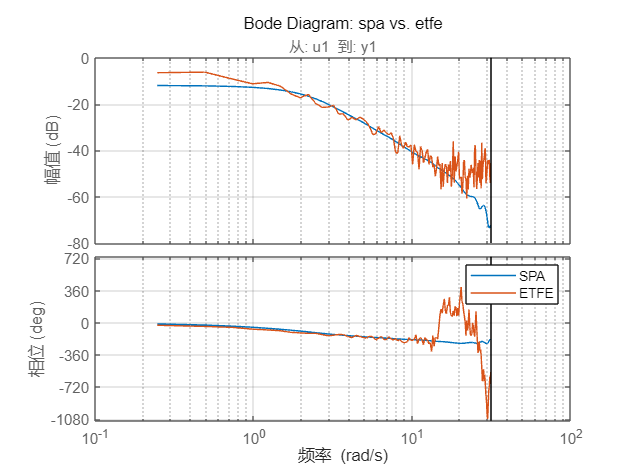

%---------------------------------------------------------------
spa_result = spa(data);

etfe_result = etfe(data);

figure;

bode(spa_result);
hold on;
title('Bode Diagram: spa vs. etfe');
grid on;

bode(etfe_result);

legend('SPA', 'ETFE');


%---------------------------------------------------------------

# **Problem 2 (5 points)**

- **The figure below shows the monthly USD prices of Bitcoin and Ethereum for the last three years (11.2020-10.2023). The related data are stored in the “data1.mat” datafile.**

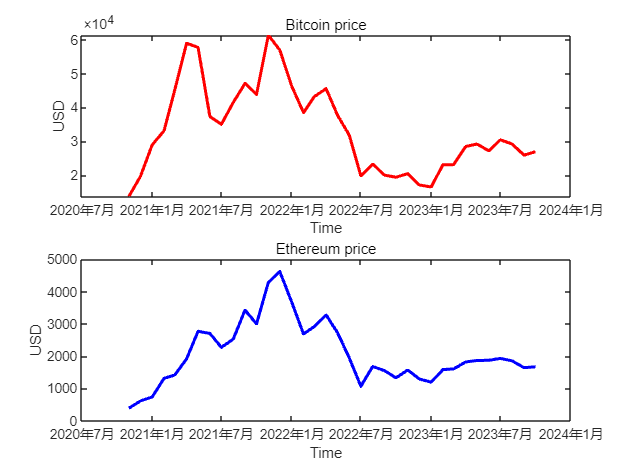

clear

load('data1.mat')

figure
subplot(2,1,1)
plot(time,bitcoin,'color','r','linewidth',2); ylabel('USD'); xlabel('Time'); title('Bitcoin price')
subplot(2,1,2)
plot(time,ethereum,'b','linewidth',2); ylabel('USD'); xlabel('Time'); title('Ethereum price')

## **a)**

- Analyze the quantitative relationship between the Bitcoin and Ethereum prices, i.e., determine whether they are correlated or not. Briefly explain the methodology behind your analysis and include the necessary calculations in the script below.

**(1.5 points) **

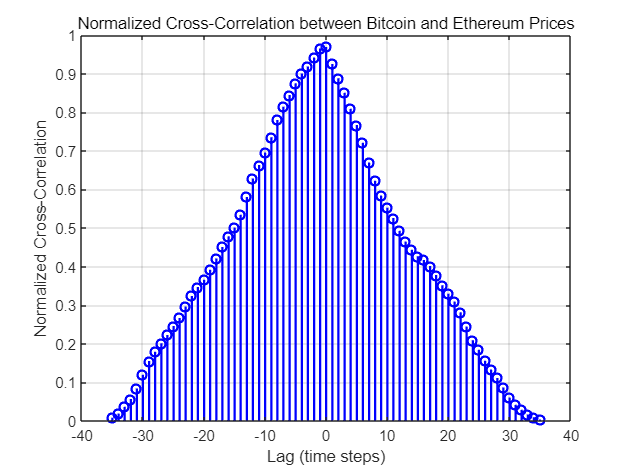

%---------------------------------------------------------------
[r, lags] = xcorr(bitcoin, ethereum, 'coeff');
figure;
stem(lags, r, 'b', 'LineWidth', 1.5);
title('Normalized Cross-Correlation between Bitcoin and Ethereum Prices');
xlabel('Lag (time steps)');
ylabel('Normalized Cross-Correlation');
grid on;


% The result of xcorr can be interpreted as an estimate of the correlation 
% between two random sequences or as the deterministic correlation between 
% two deterministic signals.The largest spike occur at zero lag, 
% so you can see without the lag, The croos-rlation between Bitcoin and ethereum 
% almost reach 0.95 which means they are highly related
%---------------------------------------------------------------

# Your Answer Below

## **b)**

- **Model selection:** Estimate a polynomial model to predict the Bitcoin price using the Ethereum price as an input. What polynomial order would you choose, and why? Provide your answer below. For estimation, you can use either MATLAB's Curve Fitting Toolbox or the [**polyfit**](https://se.mathworks.com/help/matlab/ref/polyfit.html) and [**polyval**](https://se.mathworks.com/help/matlab/ref/polyval.html) functions. If you decide to use Curve Fitting Toolbox, save the Toolbox-generated code in a separate script named "createFit.m" and call it from the script below to fit the chosen model. **Hint: **You can split the data into training and validation sets.

- **Visualize: **Make a [**scatter plot**](https://se.mathworks.com/help/matlab/ref/scatter.html) of the data (Bitcoin and Ethereum prices). On the same figure, plot the estimated function.

- **Predict **the Bitcoin price for the Ethereum price of 6000 USD.

**(3.5 points) **

%---------------------------------------------------------------
poly_orders = 1:5;

SSE_poly = zeros(size(poly_orders));

training_ratio = 0.75;
validation_ratio = 0.25;

total_samples = length(time);
training_samples = round(training_ratio * total_samples);
validation_samples = round(validation_ratio * total_samples);

figure;
scatter(ethereum(1:training_samples), bitcoin(1:training_samples), 'r', 'filled', 'DisplayName', 'Training Data');
hold on;
scatter(ethereum(validation_samples+1:end), bitcoin(validation_samples+1:end), 'b', 'filled', 'DisplayName', 'Validation Data');
for i = 1:length(poly_orders)
    p = polyfit(ethereum(1:training_samples), bitcoin(1:training_samples), poly_orders(i));

    % Use the polynomial to predict Bitcoin prices on the validation data
    f = polyval(p, ethereum(1:validation_samples)); 

    % Calculate SSE for the current polynomial order
    
    SSE_poly(i) = sum((bitcoin(1:validation_samples)-f).^2);

    fprintf('SSE for polynomial order %d is %f\n', poly_orders(i), SSE_poly(i));

    % Plot the polynomial fit
    plot(ethereum(1:validation_samples), f, 'DisplayName', sprintf('Order %d', poly_orders(i)));
end

SSE for polynomial order 1 is 1391013322.709510
SSE for polynomial order 2 is 1353670739.650205
SSE for polynomial order 3 is 1368164756.174922
SSE for polynomial order 4 is 1375097758.487912
SSE for polynomial order 5 is 1377067716.250684


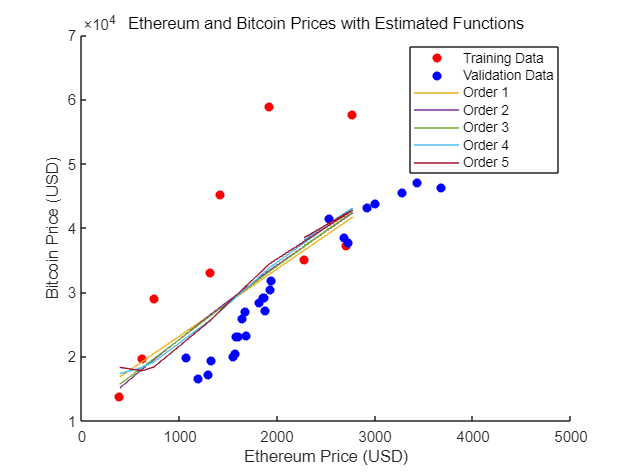


xlabel('Ethereum Price (USD)');
ylabel('Bitcoin Price (USD)');
title('Ethereum and Bitcoin Prices with Estimated Functions');
legend('show');


% Find the polynomial order with the lowest SSE
[minSSE, minOrder] = min(SSE_poly);

fprintf('The best polynomial order to predict Bitcoin price using Ethereum price is %d with SSE: %f\n', poly_orders(minOrder), minSSE);

The best polynomial order to predict Bitcoin price using Ethereum price is 2 with SSE: 1353670739.650205


ethereum_price_to_predict = 6000;
predicted_bitcoin_price = polyval(polyfit(ethereum, bitcoin, poly_orders(minOrder)), ethereum_price_to_predict);

fprintf('Predicted Bitcoin price for Ethereum price of $%.2f: $%.2f\n', ethereum_price_to_predict, predicted_bitcoin_price);

Predicted Bitcoin price for Ethereum price of $6000.00: $73980.27


%---------------------------------------------------------------

# **What to return?**

You are expected to submit your assignment to the related link for Assignment 4 on MyCourses.

Your submission should include:

- One completed .mlx file: **Assignment_4_*your_student_number*.mlx**

- MATLAB script:** createFit.m **(optional)